% 读取 CSV 文件
data = readtable('/Threshold24_mean_3sd.csv');

% 确保"no"列存在
if ismember('No', data.Properties.VariableNames)
    % 分离奇数和偶数行
    oddData = data(mod(data.No, 2) == 1, :);  % "no”列值为奇数的行
    evenData = data(mod(data.No, 2) == 0, :); % "no”列值为偶数的行

    % 将分离后的数据写入新的 CSV 文件
    writetable(oddData, 'Threshold24_mean_3sd_odd.csv');
    writetable(evenData, 'Threshold24_mean_3sd_even.csv');
else
    error('列 "No" 不存在于数据中。');
end

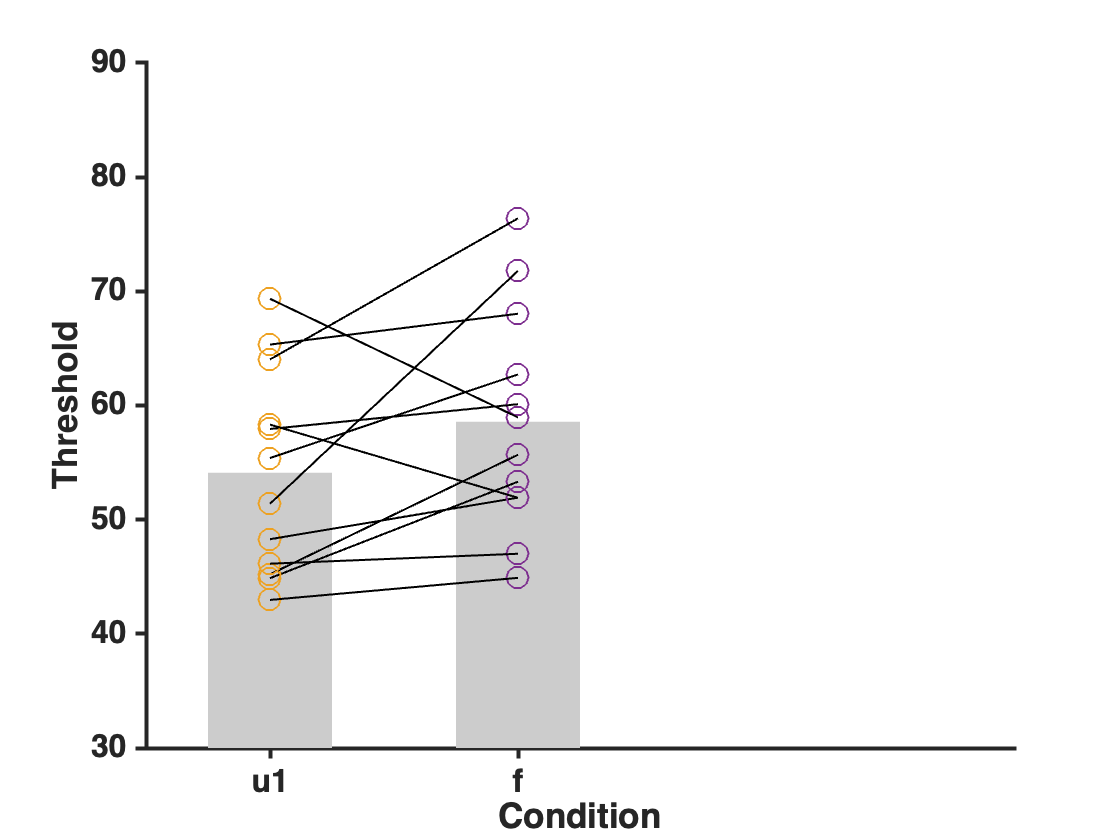

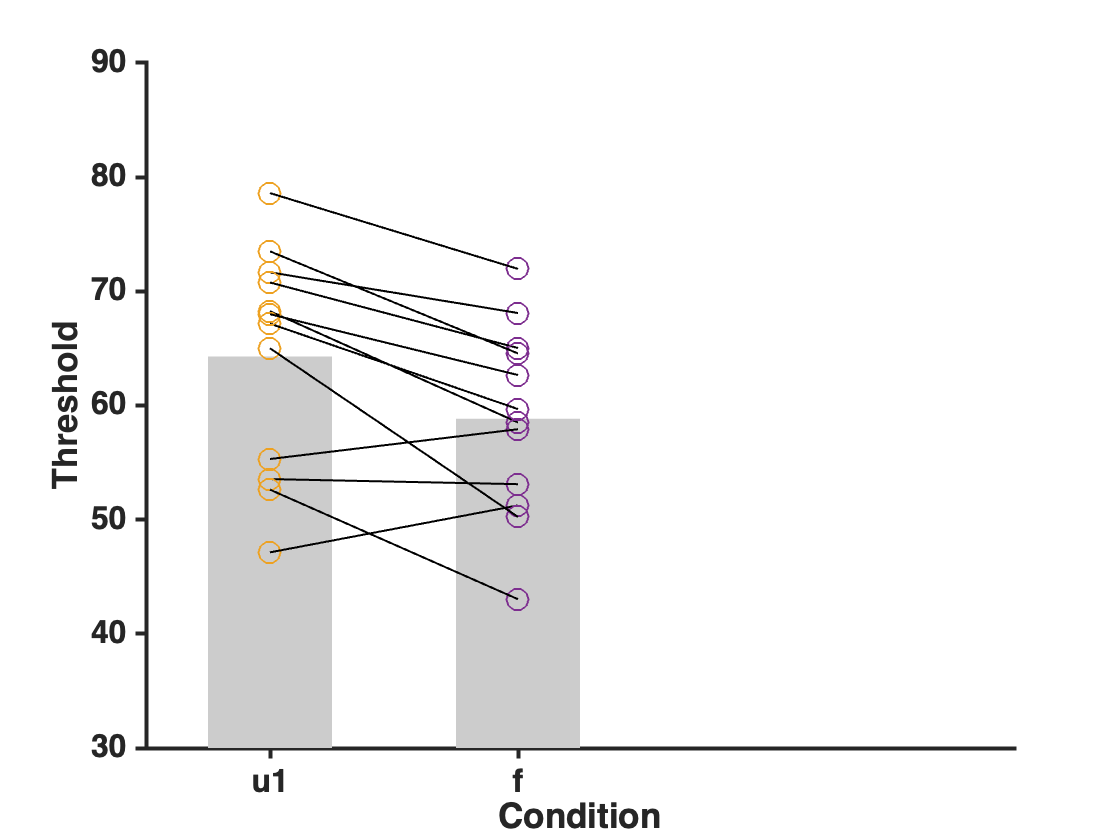

% 定义文件名
files = {'Threshold24_mean_3sd_odd.csv', 'Threshold24_mean_3sd_even.csv'};

% 遍历文件
for k = 1:length(files)
    % 读取数据
    data = readtable(files{k});

    % 提取No、condition和threshold列的数据
    No = data.No;
    condition = data.condition;
    threshold = data.Threshold;

    % 筛选条件为 'u1' 和 'f' 的数据
    idx = strcmp(condition, 'u1') | strcmp(condition, 'f');
    No = No(idx);
    condition = condition(idx);
    threshold = threshold(idx);

    % 获取唯一的No值
    unique_No = unique(No);

    % 初始化画布
    figure;
    hold on;

    % 计算并绘制每个条件的平均值
    mean_values = zeros(1, 2); % 初始化平均值数组，假设有两个条件
    conditions = {'u1', 'f'}; % 定义条件
    for i = 1:length(conditions)
        mean_values(i) = mean(threshold(strcmp(condition, conditions{i})));
    end

    % 在同一图表中绘制平均值的柱状图
    bar_positions = [1, 2]; % 柱状图的位置
    bar(bar_positions, mean_values, 0.5, 'FaceColor', [0.8, 0.8, 0.8], 'EdgeColor', 'none'); % 绘制柱状图


    % 循环绘制每个人的数据
    for i = 1:numel(unique_No)
        % 提取当前人的数据
        cur_idx = No == unique_No(i);
        cur_condition = condition(cur_idx);
        cur_threshold = threshold(cur_idx);

        % 将condition转换为数值（u1->1，f->2）
        cur_condition_num = zeros(size(cur_condition));
        for j = 1:length(cur_condition)
            if strcmp(cur_condition{j}, 'u1')
                cur_condition_num(j) = 1;
            elseif strcmp(cur_condition{j}, 'f')
                cur_condition_num(j) = 2;
            end
        end

        % 使用不同颜色绘制点
        for j = 1:length(cur_condition_num)
            if cur_condition_num(j) == 1
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.93, 0.63, 0.13], 'MarkerSize', 11, 'Linewidth', 1);
            else
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.49, 0.18, 0.56], 'MarkerSize', 11, 'Linewidth', 1);
            end
        end

        % 绘制连线 
        for j = 1:length(cur_condition_num)-1
            line([cur_condition_num(j), cur_condition_num(j+1)], [cur_threshold(j), cur_threshold(j+1)], 'Color', 'k', 'Linewidth', 1);
        end
    end


    % 设置图表其他属性
    xlabel('Condition', 'FontSize', 40, 'FontWeight', 'bold');
    ylabel('Threshold', 'FontSize', 40, 'FontWeight', 'bold');
    xticks([1 2]);
    xticklabels({'u1', 'f'});
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    ax = gca;
    ax.FontWeight = 'bold';
    ax.LineWidth = 2;
    ax.TickDir = 'out';
    xlim([0.5 4]);
    ylim([30 90]);

    % 保存图像
    filename = sprintf('plot_%s.png', files{k});
    saveas(gcf, filename);
end

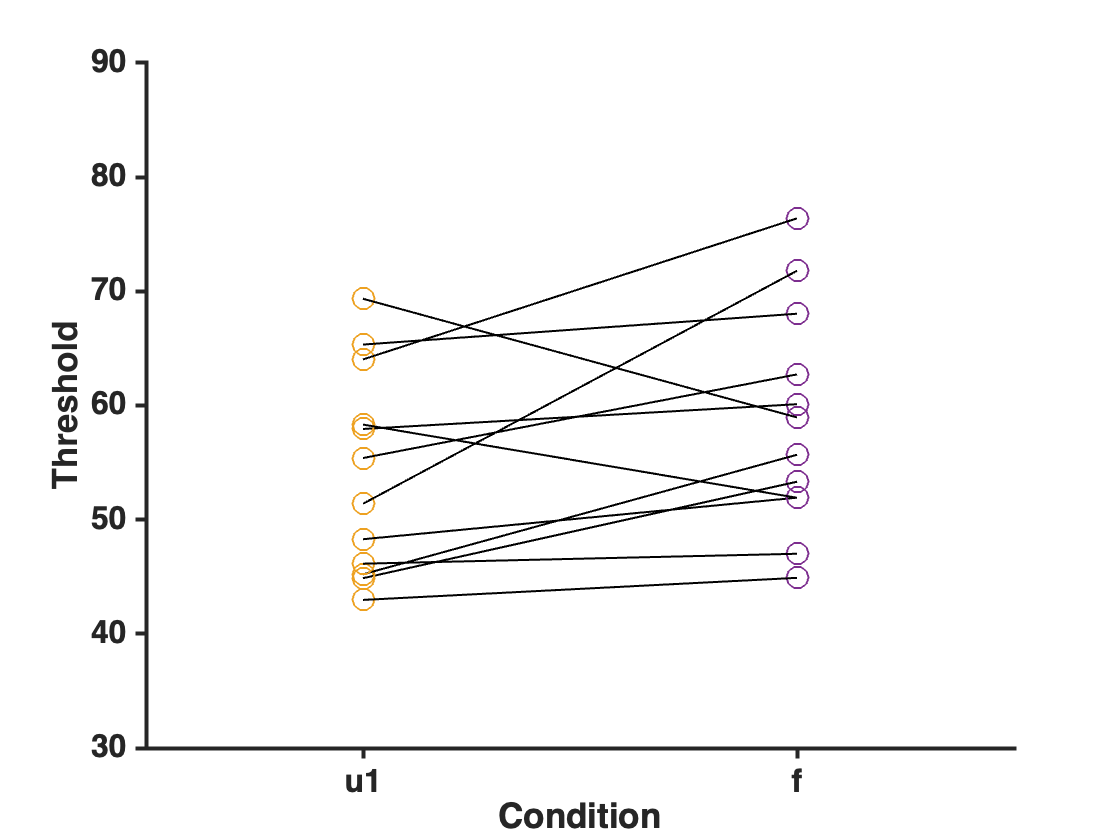

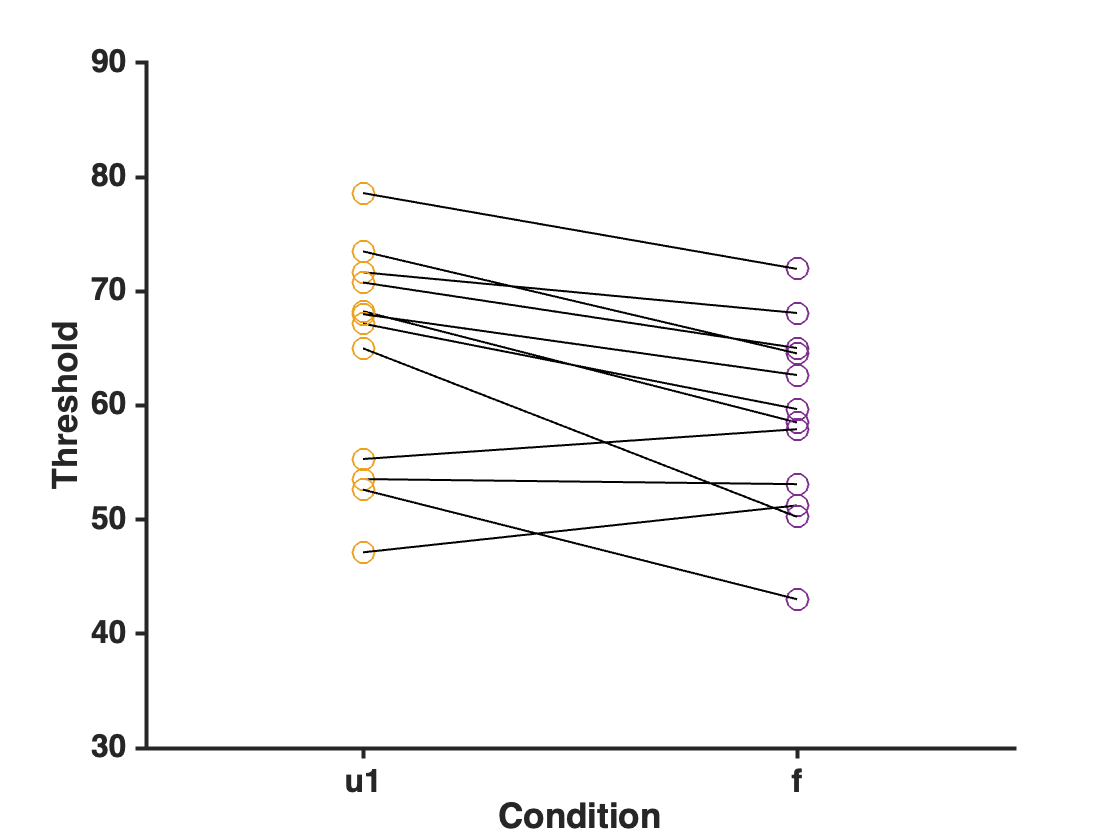

% 定义文件名
files = {'Threshold24_mean_3sd_odd.csv', 'Threshold24_mean_3sd_even.csv'};

% 遍历文件
for k = 1:length(files)
    % 读取数据
    data = readtable(files{k});

    % 提取No、condition和threshold列的数据
    No = data.No;
    condition = data.condition;
    threshold = data.Threshold;

    % 筛选条件为 'u1' 和 'f' 的数据
    idx = (condition == "u1") | (condition == "f");
    No = No(idx);
    condition = condition(idx);
    threshold = threshold(idx);

    % 获取唯一的No值
    unique_No = unique(No);

    % 初始化画布
    figure;
    hold on;

    % 循环绘制每个人的数据
    for i = 1:numel(unique_No)
        % 提取当前人的数据
        cur_idx = No == unique_No(i);
        cur_condition = condition(cur_idx);
        cur_threshold = threshold(cur_idx);

        % 将condition转换为数值（u1->1，f->2）
        cur_condition_num = zeros(size(cur_condition));
        cur_condition_num(cur_condition == "u1") = 1;
        cur_condition_num(cur_condition == "f") = 2;

        % 使用不同颜色绘制点
        for j = 1:length(cur_condition_num)
            if cur_condition_num(j) == 1
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.93, 0.63, 0.13], 'MarkerSize', 11, 'Linewidth', 1);
            else
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.49, 0.18, 0.56], 'MarkerSize', 11, 'Linewidth', 1);
            end
        end

        % 绘制连线 
        for j = 1:length(cur_condition_num)-1
            line([cur_condition_num(j), cur_condition_num(j+1)], [cur_threshold(j), cur_threshold(j+1)], 'Color', 'k', 'Linewidth', 1);
        end
    end

    % 设置横纵坐标名称
    xlabel('Condition', 'FontSize', 40, 'FontWeight', 'bold');
    ylabel('Threshold', 'FontSize', 40, 'FontWeight', 'bold');

    % 设置横坐标刻度和标签
    xticks([1 2]);
    xticklabels({'u1', 'f'});
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');

    % 设置坐标轴的粗细
    ax = gca;
    ax.FontWeight = 'bold';
    ax.LineWidth = 2;

    % 设置坐标轴的刻度朝外
    ax.TickDir = 'out';

    % 设置横纵坐标范围
    xlim([0.5 2.5]);
    ylim([30 90]);

    % 保存图像
    filename = sprintf('plot_%s.png', files{k});
    saveas(gcf, filename);
end

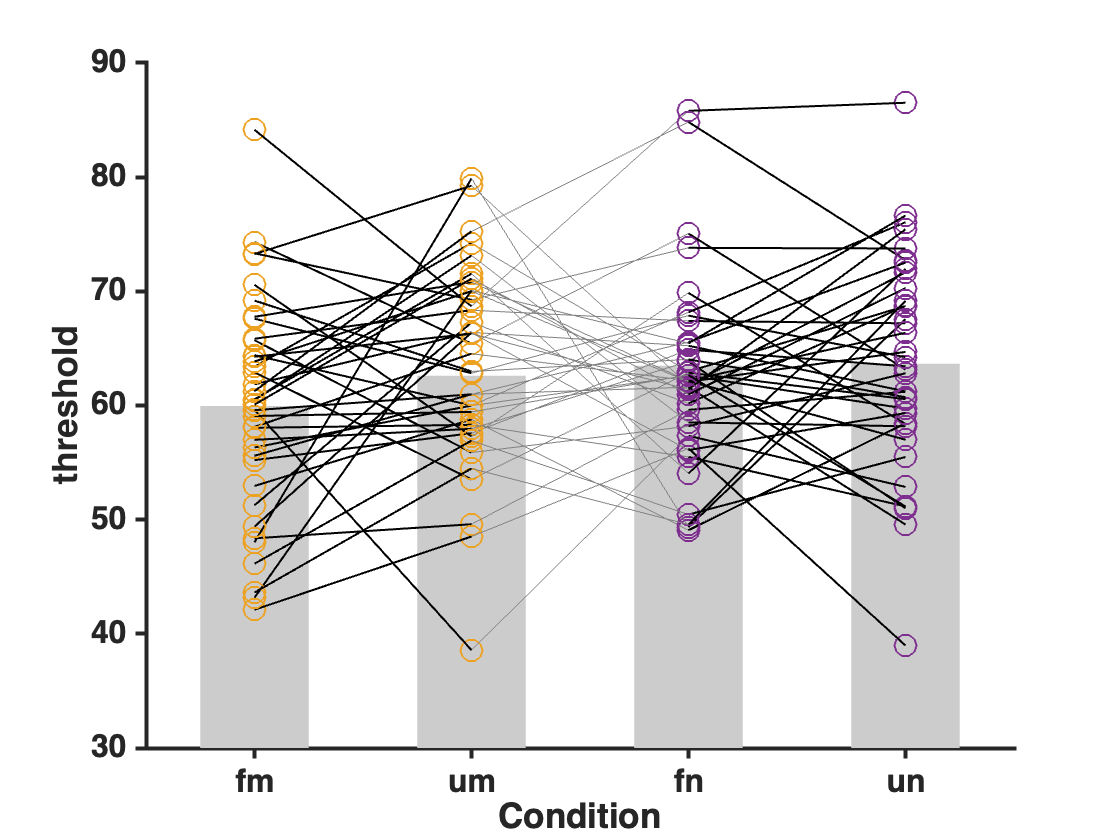

% 读取所有conditions的数据绘制条形图
data = readtable('20230804datacheck/psychometric_raw.csv');

% 提取No、condition和threshold列的数据
No = data.No;
condition = data.condition;
threshold = data.threshold;

% 获取唯一的No值
unique_No = unique(No);
% 获取唯一的条件值
unique_conditions = unique(condition);

% 初始化存储平均值的数组
mean_values = zeros(size(unique_conditions));

% 计算每种条件的平均值
for i = 1:numel(unique_conditions)
    cur_condition = unique_conditions(i);
    cur_threshold = threshold(strcmp(condition, cur_condition));
    mean_values(i) = mean(cur_threshold);
end

% 初始化画布
figure;
hold on;

% 绘制柱状图
%bar(1:numel(unique_conditions), mean_values, 0.5, 'g');
bar(1:numel(unique_conditions), mean_values, 0.5,'FaceColor',[0.8, 0.8, 0.8],'EdgeColor','none');
%bar(y,'FaceColor',[0 .5 .5],'EdgeColor',[0 .9 .9],'Linewidth',1.5)

xticks(1:numel(unique_conditions));
xticklabels(unique_conditions);
xlabel('Condition');
ylabel('Mean threshold');


% 读取数据
data = readtable('20230804datacheck/psychometric_raw.csv');

% 提取No、condition和threshold列的数据
No = data.No;
condition = data.condition;
threshold = data.threshold;

% 获取唯一的No值
unique_No = unique(No);
% 获取唯一的条件值
unique_conditions = unique(condition);

% 判断当前条件的数据
    if sum(cur_condition == "fm") > 0 && sum(cur_condition == "um") > 0 && um(cur_condition == "fn") > 0 && sum(cur_condition == "un") > 0
        % 将condition转换为数值（fm->1，um->2）
        cur_condition_num = zeros(size(cur_condition));
        cur_condition_num(cur_condition == "fm") = 1;
        cur_condition_num(cur_condition == "um") = 2;
        cur_condition_num(cur_condition == "fn") = 3;
        cur_condition_num(cur_condition == "un") = 4;
        
        % 绘制直方图
        bar(cur_condition_num,mean_values);
    end

% 循环绘制每个人的折线图
for i = 1:numel(unique_No)
    % 提取当前人的数据
    idx = No == unique_No(i);
    cur_condition = condition(idx);
    cur_threshold = threshold(idx);
    
    % 判断当前人是否有fm和um条件的数据
    if sum(cur_condition == "fm") > 0 && sum(cur_condition == "um") > 0 && sum(cur_condition == "fn") > 0 && sum(cur_condition == "un") > 0
        % 将condition转换为数值（fm->1，um->2）
        cur_condition_num = zeros(size(cur_condition));
        cur_condition_num(cur_condition == "fm") = 1;
        cur_condition_num(cur_condition == "um") = 2;
        cur_condition_num(cur_condition == "fn") = 3;
        cur_condition_num(cur_condition == "un") = 4;
        
        % 绘制当前人的折线图
        % 黑色，1
        % plot(cur_condition_num, cur_threshold, 'k-', 'Linewidth', 1);
        % 灰色，0.5
        % plot(cur_condition_num, cur_threshold, '-', 'Color', [0.5, 0.5, 0.5], 'Linewidth', 0.5);
        
        %plot(cur_condition_num, cur_threshold, 'o', 'Color',[0.93, 0.63, 0.13],'MarkerSize', 11, 'Linewidth', 1);
         % 使用不同颜色绘制点，根据条件判断
        for j = 1:length(cur_condition_num)
            if cur_condition_num(j) == 3 || cur_condition_num(j) == 4
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.49, 0.18, 0.56], 'MarkerSize', 11, 'Linewidth', 1);
            else
                plot(cur_condition_num(j), cur_threshold(j), 'o', 'Color', [0.93, 0.63, 0.13], 'MarkerSize', 11, 'Linewidth', 1);
            end
        end

        % 绘制连线 
        for j = 1:length(cur_condition_num)-1
            if cur_condition_num(j) == 1 && cur_condition_num(j+1) == 2
                line([cur_condition_num(j), cur_condition_num(j+1)], [cur_threshold(j), cur_threshold(j+1)], 'Color', 'k', 'Linewidth', 1);
            elseif cur_condition_num(j) == 2 && cur_condition_num(j+1) == 3
                line([cur_condition_num(j), cur_condition_num(j+1)], [cur_threshold(j), cur_threshold(j+1)], 'Color', [0.5, 0.5, 0.5], 'Linewidth', 0.5);
            elseif cur_condition_num(j) == 3 && cur_condition_num(j+1) == 4
                line([cur_condition_num(j), cur_condition_num(j+1)], [cur_threshold(j), cur_threshold(j+1)], 'Color', 'k', 'Linewidth', 1);
            end
        end
    end
end


%plot(cur_condition_num, cur_threshold, 'o', 'Color',[0.49, 0.18, 0.56],'MarkerSize', 11, 'Linewidth', 1);


% 设置横纵坐标名称
xlabel('Condition', 'FontSize', 40, 'FontWeight', 'bold');
ylabel('threshold', 'FontSize', 40, 'FontWeight', 'bold');


% 设置横坐标刻度和标签（标签和之前的赋值对齐）
xticks([1 2 3 4]);
xticklabels({'fm', 'um', 'fn', 'un'});
set(gca, 'FontSize', 16, 'FontWeight', 'bold');  % 设置坐标刻度标签的字号

% 设置坐标轴的粗细
ax = gca;
ax.FontWeight = 'bold';
ax.LineWidth = 2;

% 设置坐标轴的刻度朝外
ax.TickDir = 'out';


% 设置横坐标范围（表示横轴的取值范围）
xlim([0.5 4.5]);

% 设置纵坐标范围
ylim([30 90]);


% 保存图像
filename = '20230804datacheck/plot/Threshold_raw_1.5.png';
saveas(gcf, filename);